## Math-411 Numerical Analysis  HW 3

Nathaniel Valla

format long

1. Let $f(x) =x^4 -7x^3+18x^2-20x+8
$. Does Newton’s Method converge quadratically to the root $r = 2$ ?. Find $\lim_{x\to\infty} \frac{e_{i+1}}{e_{i}$, where ei denotes the error at step $i
$.

$f(x)$ is defined to be    $f(x) =x^4 -7x^3+18x^2-20x+8
$

f=@(x) x^4 -7*x^3+18*x^2-20*x+8;
f(2)

ans =      0


so $f'(x) =4x^3 -21x^2+36x-20$

fp=@(x) 4*x^3 -21*x^2+36*x-20;
fp(2)

ans =      0


so $f''(x) =12x^2 -42x+36$

fpp=@(x) 12*x^2 -42*x^1+36;
fpp(2)

ans =      0


so $f'''(x) =24x -42$

fppp=@(x) 24*x -42;
fppp(2)

ans =      6


$r(x) 
$ is define to be newton method of $f(x)$


$$\Rightarrow r(x) = x-\frac{f(x)}{f'(x)}
$$


Test for covergence using fixed point thereom

$\Rightarrow r'(x) = 1-\frac{(f'(x))^2-f(x)f''(x)}{(f'(x))^2}
$     since $f'(2) = 0 

$  we have to take the limit x goes to 2 


$$r'(2)  \rightarrow \lim_{x\to2}  1-\frac{(f'(x))^2-f(x)f''(x)}{(f'(x))^2} \rightarrow  \lim_{x\to2}  1 - \lim_{x\to2}\frac{(f'(x))^2}{(f'(x))^2} +\lim_{x\to2}\frac{f(x)f''(x)}{(f'(x))^2}
$$
 

        $ \rightarrow 1 - 1  +\lim_{x\to2}\frac{f(x)f''(x)}{(f'(x))^2}

$  since $\frac{0}{0}
$  use L'Hopital   

        
$$\rightarrow  \lim_{x\to2}\frac{f'(x)f''(x)+f(x)f'''(x)}{2f'(x)f''(x)}$$


        
$$\rightarrow  \lim_{x\to2}\frac{f'(x)f''(x)}{2f'(x)f''(x)}  +  \lim_{x\to2}\frac{f(x)f'''(x)}{2f'(x)f''(x)}$$
   

        $\rightarrow  1/2  +  \lim_{x\to2}\frac{f(x)f'''(x)}{2f'(x)f''(x)}$  since $\frac{0}{0}
$  use L'Hopital  

        $\rightarrow  1/2  + 1/2 \lim_{x\to2}\frac{f(x)f^{(4)}(x)+f'(x)f'''(x)}{f''(x)f''(x)+f'(x)f'''(x)}$  since $\frac{0}{0}
$  use L'Hopital  

        
$$\rightarrow  1/2  + 1/2 \lim_{x\to2}\frac
{f(x)f^{(5)}(x)+f'(x)f^{(4)}(x)+f''(x)f'''(x)+f'(x)f^{(4)}(x)}
{f'''(x)f''(x)+f''(x)f'''(x)+f''(x)f'''(x)+f'(x)f^{(4)}(x)}$$
  

        $\rightarrow  1/2  + 1/2 \lim_{x\to2}\frac
{f(x)f^{(5)}(x)+f''(x)f'''(x)+2f'(x)f^{(4)}(x)}
{3f'''(x)f''(x)+f'(x)f^{(4)}(x)}$  since $\frac{0}{0}
$  use L'Hopital

        
$$\rightarrow  1/2  + 1/2 \lim_{x\to2}\frac
{f(x)f^{(6)}(x)+f'(x)f^{(5)}(x)+f''(x)f^{(4)}(x)+f'''(x)f'''(x)+2(f''(x)f^{(4)}(x)+f'(x)f^{(5)}(x))}

{3(f'''(x)f'''(x)+f^{(4)}(x)f''(x))+f''(x)f^{(4)}(x)+f'(x)f^{(5)}(x)}$$
  

       since there now term that don't equal zero on the top and bottom we plug in and reduce

        
$$\rightarrow  1/2  + 1/2 \lim_{x\to2}\frac
{f'''(x)f'''(x)}

{3f'''(x)f'''(x)}$$
 

        
$$\rightarrow  1/2  + 1/2 \lim_{x\to2}\frac{1}
{3}$$
                                    

        
$$\rightarrow  1/2  + 1/2*1/3$$



$$r'(2)  \rightarrow \frac {4}6$$


since  $r'(2) < 1$is less the one $\lim_{x\to\infty} \frac{e_{i+1}}{e_{i}$ tends towards $0$

but since $r'(2) \not =  0$  it doesn't have quadratic convergence 

2.Each equation has one root. Use Newton’s method to approximate the root to eight correct decimal places. 

    (a) $x^3 = 2x +2
$

f= @(x) x^3-2*x-2;
fp= @(x) 3*x^2-2;
r= @(x) x-f(x)/fp(x);

guess = 1;
for i = 1:8
    guess = r(guess);
end 

    (b) $e^x+x=7$

f= @(x) exp(x)+x-7;
fp= @(x) exp(x)+1;
r= @(x) x-f(x)/fp(x);

guess = 1;
for i = 1:6
    guess = r(guess);
end 

    (c) $e^x+\sin (x) = 4$

f= @(x) exp(x)+sin(x)-4;
fp= @(x) exp(x)+cos(x);
r= @(x) x-f(x)/fp(x);

guess = 1;
for i = 1:4
    guess = r(guess);
end 

3.Apply Newton’s Method to find the only root to as much accuracy as possible and find the root’s multiplicity. Then use Modified Newton’s Method to converge to the root quadratically. Report the forward and backward error of the best approximation obtained from each method. 

(a)  $f(x) = 27x^3 +54x^2 +36x+8$

f= @(x) 27*x^3+54*x^2+36*x+8;
fp= @(x) 81*x^2+108*x+36;
r= @(x) x-f(x)/fp(x);

guess = 1;
for i = 1:40
    guess = r(guess);
end 
guess

guess =   -0.666664832347452


fp(guess)

ans =      2.725428771555016e-10


fpp=@(x) 162*x+108;
fpp(guess)

ans =      2.971597127015002e-04


fppp=@(x) 108;
fppp(guess)

ans =    108


Since $f'''(x) \not= 0$ at the root and it is the first non zero dervative  we have a mulitplciaty of 3

m = @(x) x - (f(x)*fp(x))/((fp(x))^2 -f(x)*fpp(x));

guess = -.5;
for i = 1:1
    guess = m(guess);
end 
guess

guess =   -0.666666666666667


(b) $f(x) = 36x^4 -12x^3 +37x^2 -12x+1$

f= @(x) 36*x^4 -12*x^3 +37*x^2 -12*x+1;
fp= @(x) 144*x^3 -36*x^2 +74*x -12;
r= @(x) x-f(x)/fp(x);

guess = 1;
for i = 1:40
    guess = r(guess);
end 
guess

guess =    0.166666669054496


fp(guess)

ans =      1.766993413809814e-07


fpp=@(x) 432*x^2 -72*x +74;
fpp(guess)

ans =   74.000000171923688


Since $f''(x) \not= 0$ at the root and it is the first non zero dervative we have a mulitplciaty of 2

m = @(x) x - (f(x)*fp(x))/((fp(x))^2 -f(x)*fpp(x));

guess = 1;
for i = 1:8
    guess = m(guess);
end 
guess

guess =    0.166666666400369


4. Consider the function$ f(x) = e^{\sin^3(x)} +x^6 -2x^4 -x^3 -1$ on the interval [−2,2]. Plot the function on the interval, and find all three roots to six correct decimal places. Determine which roots converge quadratically, and find the multiplicity of the roots that converge linearly.

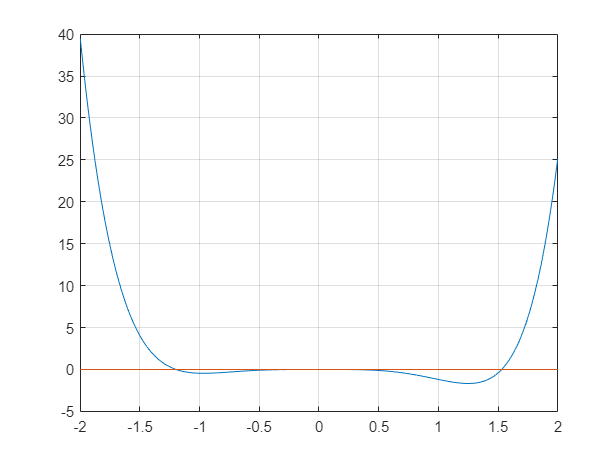

f= @(x) exp((sin(x)).^3) + x.^6 -2*x.^4- x.^3 -1; 
z=@(x) 0*x;
t = -2:0.001:2;
plot(t,f(t))
hold on 
grid on 
plot(t,z(t))

fp =@(x) x^2*(-3 -8*x + 6*x^3)+ 3*exp(sin(x)^3)*cos(x)*sin(x)^2;
fpp=@(x) 6*x*(-1-4*x+5*x^3)-3*exp(sin(x)^3)*sin(x)^3+3*exp(sin(x)^3)*cos(x)^2*sin(x)*(2+3*sin(x)^3);
fppp=@(x) 6*(-1-8*x+20*x^3)+3*exp(sin(x)^3)*cos(x)*(-sin(x)^2*(1 + 3*sin(x)^3) + cos(x)^2*(2 + 18*sin(x)^3 + 9*sin(x)^6));
fp4=@(x) 6*(-8+60*x^2)+3*exp(sin(x)^3)*sin(x)*(3*sin(x)^5+sin(x)^2+3*(9*sin(x)^6+36*sin(x^3)+20)*sin(x)*cos(x)^4-4*(9*sin(x)^6+18*sin(x)^3+2)*cos(x)^2);

fp4 = function_handle with value:
    @(x)6*(-8+60*x^2)+3*exp(sin(x)^3)*sin(x)*(3*sin(x)^5+sin(x)^2+3*(9*sin(x)^6+36*sin(x^3)+20)*sin(x)*cos(x)^4-4*(9*sin(x)^6+18*sin(x)^3+2)*cos(x)^2)


r= @(x) x-f(x)/fp(x);
guess = .0001;
for i = 1:1
    guess = r(guess);
end 
guess

guess =      8.612264570337472e-05


The root is at zero

fp(guess)

ans =     -5.110386655480147e-12


fpp(guess)

ans =     -1.780170278066658e-07


fppp(guess)

ans =   -0.004133975884102


fp4(guess)

ans =  -48.002062938237664


The multiplicity is 4

guess = 1.53;
for i = 1:5
    guess = r(guess);
end 
guess

guess =    1.530133508166615


The root is at 1.530133508

fp(guess)

ans =   14.972731159968262


The multiplicity is 1

guess = -1.19;
for i = 1:5
    guess = r(guess);
end 
guess

guess =   -1.197623722133570


The root is at -1.1976237221

fp(guess)

ans =   -4.920576858818949


The multiplicity is 1